# Reading .RAW file

## Raw files were created in VS in C

Opening the file

clear
Raw_data_on = fopen("Unprocessed Data\pump_off_start.raw"); % no white light
Raw_data_off = fopen("Unprocessed Data\pump_on_start.raw"); % no white light
%Raw_data = fopen("Image_1.raw"); % no white light
%Raw_data = fopen("Image_1_2021.10.01_123436.raw"); % no spectrometer
%Raw_data = fopen("Image_1_2021.10.15_152913.raw");

%Image = readmatrix("Unprocessed Data\test_data_2.23.22_trigmode4.csv");

Reading the file

ImageOn = fread(Raw_data_on,'uint16');
ImageOff = fread(Raw_data_off,'uint16');

Creating the dimensions and size of image

dim_Image = size(ImageOn,1);
Image_xsize = 2048;
Image_ysize = dim_Image/Image_xsize;
ImageOn = reshape(ImageOn, Image_xsize, Image_ysize);
ImageOn = ImageOn'

ImageOn =     28    22    37    38    37    42    38    39    39    38    38    41    40    41    39    39    41    41    41    41    40    42    46    39    39    45    44    44    45    41    46    44    47    47    47    47    49    52    49    50    52    56    55    59    60    61    61    61    62    65
    29    22    41    44    43    40    39    41    38    45    44    40    40    42    42    45    42    45    44    43    45    46    42    45    43    45    44    43    47    46    47    51    48    50    50    48    50    52    54    53    54    57    60    57    59    56    60    61    63    62
    25    22    42    41    39    43    40    39    40    39    41    40    40    41    43    41    44    45    42    42    46    42    45    46    43    46    42    46    45    42    47    46    48    48    50    50    52    51    53    56    56    57    57    57    60    60    60    61    66    64
    25    23    40    41    41    42    40    41    43    44    41    41    41    44   

ImageOff = reshape(ImageOff, Image_xsize, Image_ysize);
ImageOff = ImageOff'

ImageOff =     24    21    37    39    42    39    39    39    40    41    41    41    41    41    41    40    42    43    41    45    43    43    42    44    42    43    44    46    44    45    45    47    47    46    48    48    49    50    54    54    52    53    57    59    60    60    59    62    63    63
    24    23    41    43    41    41    42    40    41    45    43    42    43    45    42    44    42    45    44    42    46    46    43    46    45    47    45    46    46    45    46    48    49    49    49    52    52    52    54    56    53    52    57    57    59    61    62    65    66    66
    23    22    41    43    42    41    42    42    40    40    41    42    40    41    45    42    46    45    44    44    45    45    45    43    45    42    44    45    44    46    48    45    48    49    50    46    51    50    55    56    57    58    57    59    61    61    63    62    66    66
    24    23    41    41    40    40    42    43    42    44    45    39    45    40  

Creating the image

% imagesc(Image')
% ylabel('Row');
% xlabel('Column');
% colorbar

Putting the data into a 2D array

%Image_arr = Image';
%Image_arr = Image;
% a = Image_arr(:,2046:2048); % last 2 columns
% b = Image_arr(:, 1:2);  % first 2 columns

Concatinate rows to plot average value of each pixel

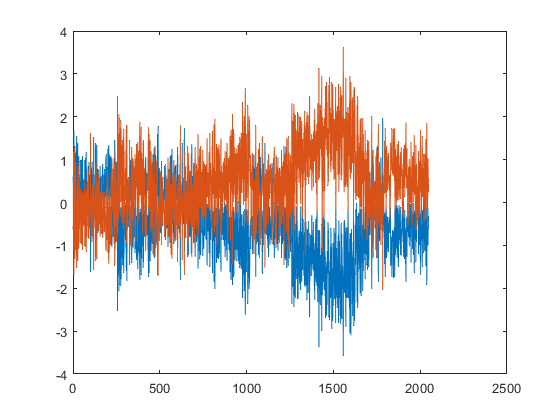

% avg_val = mean(Image_arr);
pixel = linspace(0,2048,2048);

% var(avg_val)
% plot(pixel,avg_val)
% title("Average Pixel Values for 1000 Shots")
% xlabel("pixel position")
% ylabel("avg value")

on_on_shots = ImageOn(1:2:end,:);
on_off_shots = ImageOn(2:2:end,:);

off_off_shots = ImageOff(1:2:end,:);
off_on_shots = ImageOff(2:2:end,:);

Mon = on_on_shots - on_off_shots;
%DTTon = Mon./on_off_shots;
avg_shots_on = mean(Mon);

Moff = off_on_shots - off_off_shots;
%DTToff = Moff./off_off_shots;
avg_shots_off = mean(Moff);

% %avg_even_shots = mean(even_shots);
% 
plot(pixel, avg_shots_on); hold on;
plot(pixel, avg_shots_off); hold off;

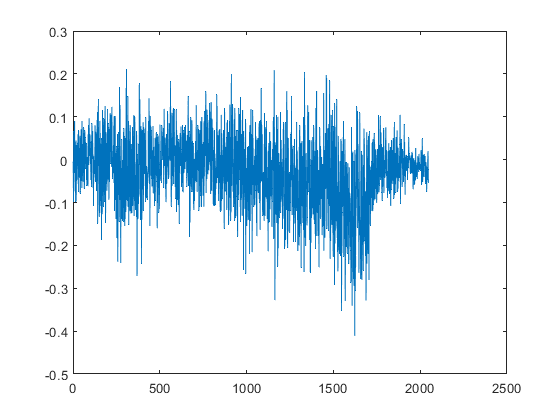


newplot
noise = avg_shots_on+avg_shots_off;
plot(noise)


% hold on
% plot(pixel, avg_even_shots)
% legend("odd shots", "even shots")
% xlabel('pixel position')
% ylabel('value')
% hold off

Pixel #490 over 1000 lines/shots

% pxl490 = Image_arr(:,490);
% time_steps = linspace(0, 444.4, 40000);
% 
% % saving the data in csv file - to compare using python
% %writematrix(pxl490, "WL_pxl490_10.15.2021.csv")
% 
% plot(time_steps, pxl490)
% title("Pixel #490 over 444.4 ms")
% ylabel("Pixel Value")
% xlabel("ms")

Variance and Covariance

% %Variance
% var(pxl490)
% std(pxl490)

Autocorrelation of single pixel over time (pixel #490)

% %[row, col] = find(isnan(pxl490))
% %if there are no NaN values in the vector why is there lag in the autocorr
% autocorr(pxl490, "NumLags", 50)
% %plot(autocorr(pxl490,"NumLags",999))
% plot(autocorr(pxl490,"NumLags",50))
% title("Autocorrelation map of pixel 490")
% 
% [acf, lags, bounds] = autocorr(pxl490);
% acf;
% lags;
% bounds;

Autoorrelation of single pixel over time with odd shots and even shots taken seperately

% pxl490_odd = (pxl490(1:2:end,:));
% var(pxl490_odd)
% std(pxl490_odd)
% pxl490_even = (pxl490(2:2:end,:));
% var(pxl490_even)
% std(pxl490_even)
% 
% ac_pxl490_odd = autocorr(pxl490_odd,"NumLags",50);
% %pc_pxl490_odd = parcorr(pxl490_odd,"NumLags",100)    
% ac_pxl490_even = autocorr(pxl490_even,"NumLags",50);
% %pc_pxl490_even = parcorr(pxl490_even,"NumLags",100)
% 
% autocorr(pxl490_odd,"NumLags",50)
% plot(ac_pxl490_odd)
% title("Autocorr of pixel 490 (odd shots)")
% autocorr(pxl490_even,"NumLags",50)
% plot(ac_pxl490_even)
% title("Autocorr of pixel 490 (even shots)")
% 

% %corr_matrix = corr(Image)
% %imagesc(corr_matrix)
% %colorbar
% %plot(diag(pixel,corr_matrix))
% %title("Correlation map of each pixel over 11.11 ms")